clc, clear, close all

months = {'April', 'May', 'June', 'July', 'August', 'September', 'October', 'November', 'December', 'January', 'February', 'March'};


h1 = readtable('dataset5.xlsx', 'Sheet', 'Hdata1', 'Range', 'B10:M40');
q1 = readtable('dataset5.xlsx', 'Sheet', 'Qdata1', 'Range', 'B11:M41');
q2 = readtable('dataset5.xlsx', 'Sheet', 'Qdata2', 'Range', 'B11:M41');

h1_data = table2array(h1);
q1_data = table2array(q1);
q2_data = table2array(q2);

h1_data(isnan(h1_data)) = 0;
q1_data(isnan(q1_data)) = 0;
q2_data(isnan(q2_data)) = 0;

h1_flat = h1_data(h1_data ~= 0);
q1_flat = q1_data(q1_data ~= 0);
q2_flat = q2_data(q2_data ~= 0);

% Remove NaN values
h1_flat = h1_flat(~isnan(h1_flat));
q1_flat = q1_flat(~isnan(q1_flat));
q2_flat = q2_flat(~isnan(q2_flat));

### Now we make bar plot to visulize distribution for each data

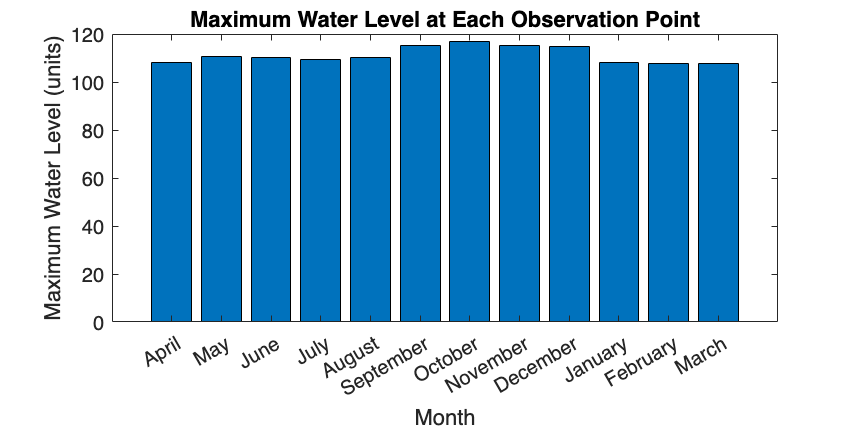

figure('Position', [100, 100, 800, 400]);
bar(max(h1_data))
xticks(1:length(months)) % Assuming there's one value per month
xticklabels(months)
xlabel('Month')
ylabel('Maximum Water Level (units)') % Specify the correct units
title('Maximum Water Level at Each Observation Point')

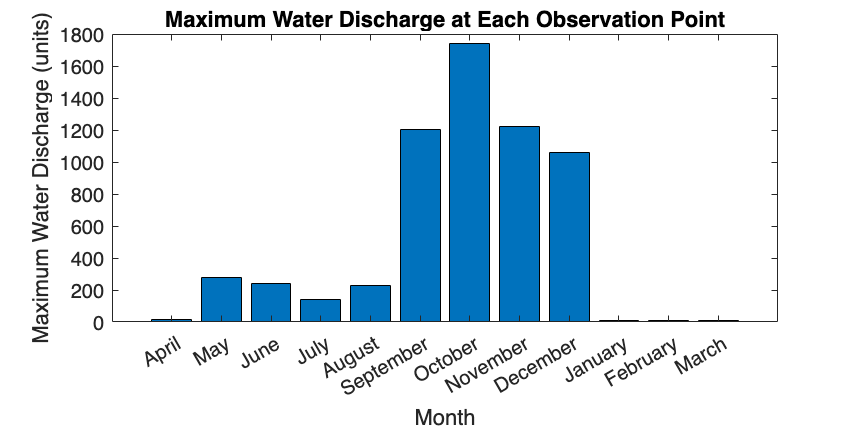

figure('Position', [100, 100, 800, 400]); % Adjust [left, bottom, width, height] as needed
bar(max(q1_data))
xticks(1:length(months)) % Assuming there's one value per month
xticklabels(months)
xlabel('Month')
ylabel('Maximum Water Discharge (units)')
title('Maximum Water Discharge at Each Observation Point')

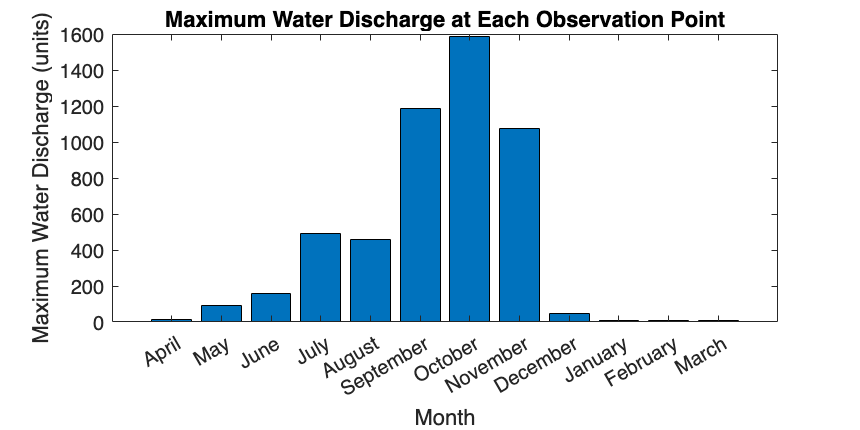

figure('Position', [100, 100, 800, 400]); % Adjust [left, bottom, width, height] as needed
bar(max(q2_data))
xticks(1:length(months)) % Assuming there's one value per month
xticklabels(months)
xlabel('Month')
ylabel('Maximum Water Discharge (units)')
title('Maximum Water Discharge at Each Observation Point')

### We make bar plot for average water level, and discharge rate for water

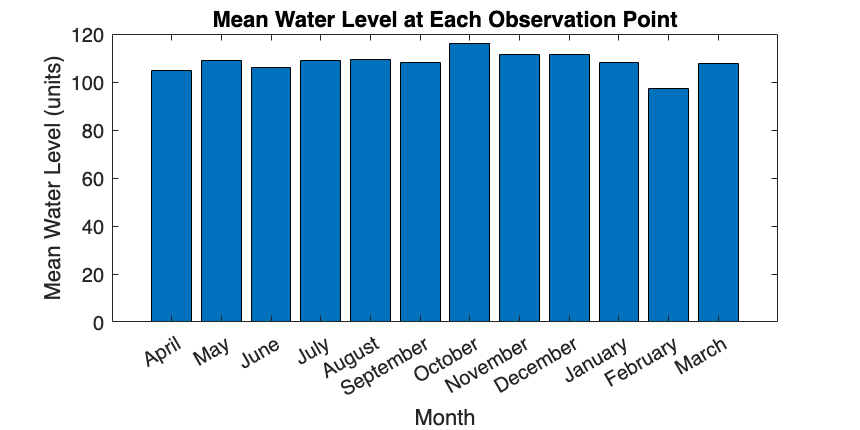

figure('Position', [100, 100, 800, 400]);
bar(mean(h1_data))
xticks(1:length(months)) % Assuming there's one value per month
xticklabels(months)
xlabel('Month')
ylabel('Mean Water Level (units)') % Specify the correct units
title('Mean Water Level at Each Observation Point')

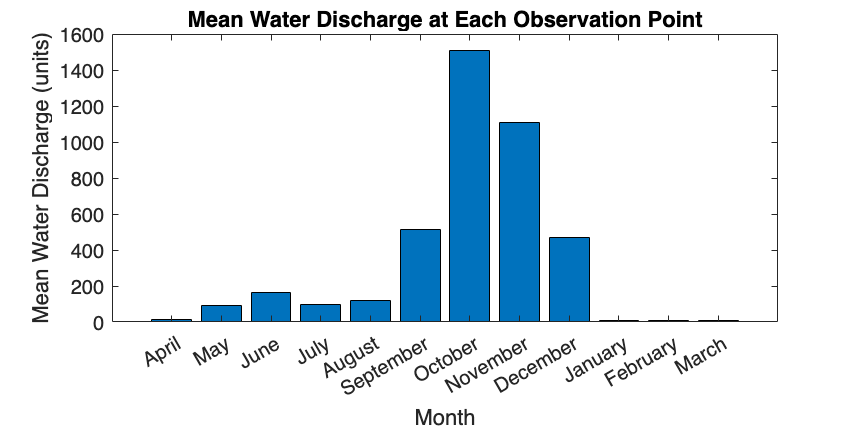

figure('Position', [100, 100, 800, 400]);
bar(mean(q1_data))
xticks(1:length(months)) % Assuming there's one value per month
xticklabels(months)
xlabel('Month')
ylabel('Mean Water Discharge (units)')
title('Mean Water Discharge at Each Observation Point')

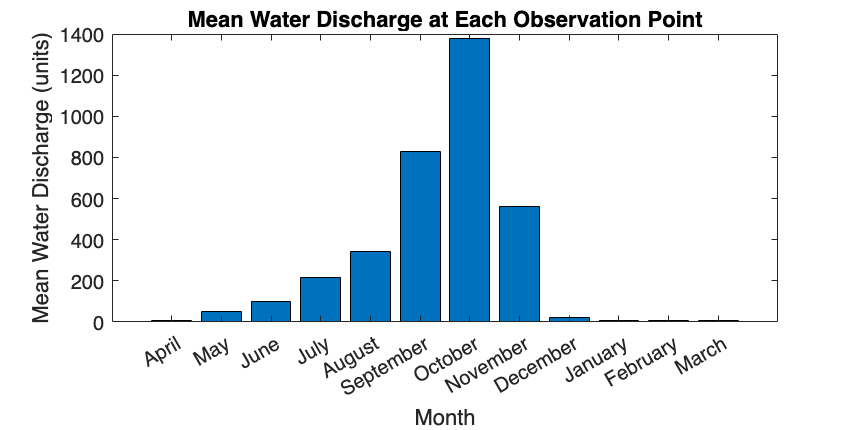

figure('Position', [100, 100, 800, 400]);
bar(mean(q2_data))
xticks(1:length(months)) % Assuming there's one value per month
xticklabels(months)
xlabel('Month')
ylabel('Mean Water Discharge (units)')
title('Mean Water Discharge at Each Observation Point')

### Line Plot for water level data and discharge data

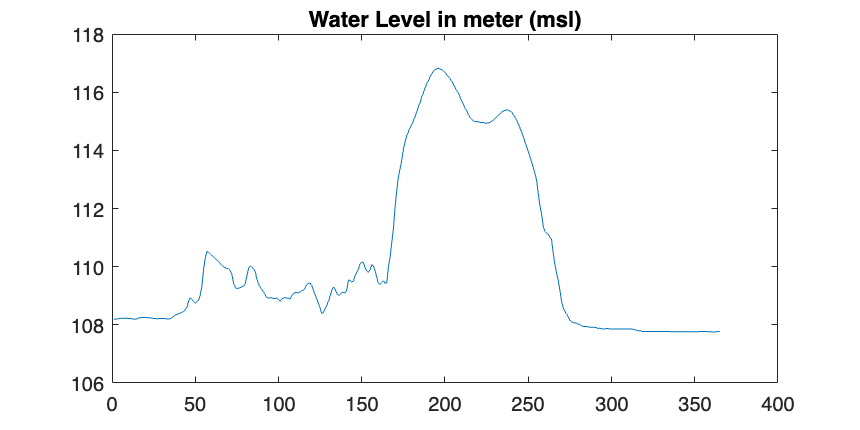

[n m] = size(q2_flat);
t = 1:size(n);
plot(h1_flat)
title("Water Level in meter (msl)")

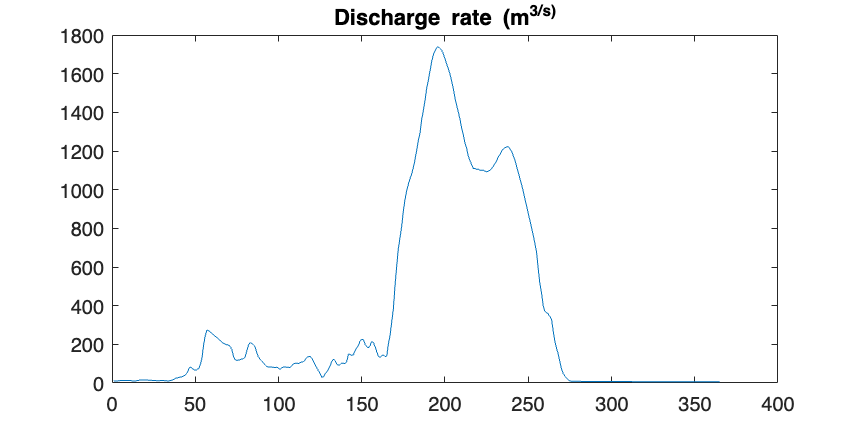

plot(q1_flat)
title("Discharge rate (m^3/s)")

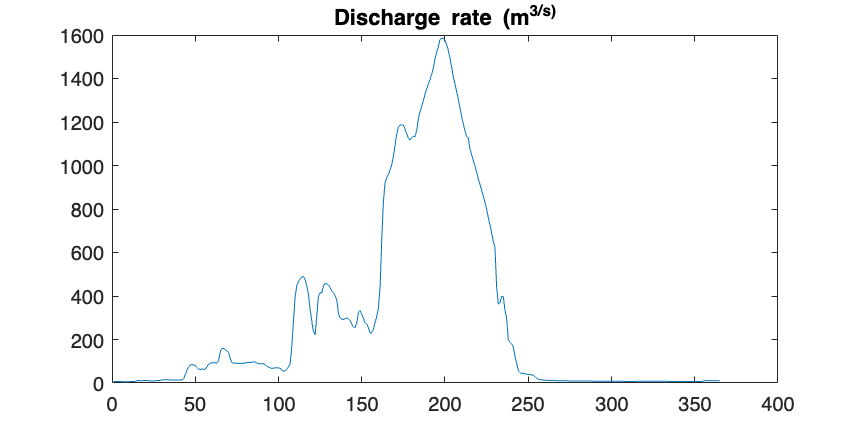

plot(q2_flat)
title("Discharge rate (m^3/s)")

### Find max/min date for each month

% Map month names to their numerical indices
month_mapping = containers.Map({'May', 'Jun', 'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec','Jan', 'Feb', 'Mar', 'Apr', }, ...
                               1:12);

% Let's say the user selects 'August'
selected_month_name = 'Aug'; % The user can directly input the month name

% Convert the month name to its numerical index using the map
selected_month = month_mapping(selected_month_name);

% Extract data for the selected month
% Assume that data for each month is in its respective column
h1_month = h1_data(:, selected_month);
q1_month = q1_data(:, selected_month);

% Remove NaN values for the selected month
valid_indices = ~isnan(q1_month);
q1_month = q1_month(valid_indices);
h1_month = h1_month(valid_indices);  % Only include corresponding h1_month values

% Find the maximum value for the selected month
maximum_value = max(q1_month);

% Find the index of the maximum value
maxIndex = find(q1_month == maximum_value, 1, 'first');  % Find the index of the first occurrence of the maximum value

% The date here should correspond to the actual year and the selected month
% Assuming the dataset starts from April 1st, 2023 and spans a full year
dataset_start_date = datetime(2023, 4, 1);  % Dataset start date is April 1st, 2023
days_in_previous_months = sum(eomday(2023, 1:selected_month-1));  % Total days in months before the selected month

% Calculate the date for the maximum value
if ~isempty(maxIndex)
    % Add one month to the dataset start date
    startDateNextMonth = dataset_start_date + calmonths(1);

    % Calculate the year and month for the next month
    nextMonthYear = year(startDateNextMonth);
    nextMonth = month(startDateNextMonth);

    % Calculate the number of days in previous months including the next month
    days_in_next_month_and_previous = sum(eomday(nextMonthYear, 1:nextMonth-1));

    % Calculate the date of maximum value in the next month
    date_of_maximum = dataset_start_date + days(days_in_next_month_and_previous + maxIndex - 1);
    maxDateStr = datestr(date_of_maximum, 'dd/mm/yyyy');
else
    maxDateStr = 'N/A';
end

% Display the results
fprintf('Maximum value for %s: %.2f\n', selected_month_name, maximum_value);

Maximum value for Aug: 138.40


fprintf('Date of maximum value for %s: %s\n', selected_month_name, maxDateStr);

Date of maximum value for Aug: 26/08/2023
